# **Constellation operation research - AMOS Research**

**UT Austin CDUS**

**Hongseok Kim**

savepath = '/Users/hongseokkim/Desktop/Redstone_MILP/RS_MILP_06_AMOS';

number_of_satellites = 48;
number_of_orbit_planes = 12;
sim_duration = 7;
inclination_angle = 98;
FOV_value = 60;


% Pilot Satellite Scinario - Input OM generation
sat_per_orbit_plane = number_of_satellites/number_of_orbit_planes;
orbit_altitude = 500; % 궤도 고도 (km)
orbit_radius = (6378 + orbit_altitude) * 1000; % 궤도 반지름 (m): r                                  입력 2.1 위성 고도 (km)

OM_pilot_sat = [ones(number_of_orbit_planes,1) * orbit_radius, ...              % SMA
                ones(number_of_orbit_planes,1) * 0, ...                         % ecc
                ones(number_of_orbit_planes,1) * inclination_angle, ...         % inc
                (0:360/number_of_orbit_planes:360-360/number_of_orbit_planes)', ... % RAAN
                ones(number_of_orbit_planes,1) * 0, ...                         % AOP
                ones(number_of_orbit_planes,1) * 0];                             % TA

start_time = datetime(2030, 1, 1, 0, 0, 0); % 시뮬레이션 시작 시간 (년, 월, 일, 시, 분, 초)               입력 2.2 시뮬레이션 시작 시간
stop_time = start_time + seconds(10000); % 시뮬레이션 시간
sample_time = 1;             % seconds
sc_pilot = satelliteScenario(start_time, stop_time, sample_time); % 시나리오 생성
propagator_options = numericalPropagator(sc_pilot, GravitationalPotentialModel="oblate-ellipsoid", ODESolver="ode78"); % J2 섭동
orbit_propagator = "numerical"; %궤도 전파기: ("numerical", "SGP4", "SDP4", "two-body-keplerian")   입력 2.3 궤도전파기 (수정 불필요)
sat_pilots = satellite(sc_pilot, OM_pilot_sat(:,1), ...
                                 OM_pilot_sat(:,2), ...
                                 OM_pilot_sat(:,3), ...
                                 OM_pilot_sat(:,4), ...
                                 OM_pilot_sat(:,5), ...
                                 OM_pilot_sat(:,6),"OrbitPropagator",orbit_propagator);

sat_OM_input = zeros(number_of_satellites,6);

for orbit_plane_index = 1:number_of_orbit_planes
  sat_OM_input((orbit_plane_index-1)*sat_per_orbit_plane+1,:) = OM_pilot_sat(orbit_plane_index,:);  
  pilot_sat_om = orbitalElements(sat_pilots(orbit_plane_index));
  pilot_sat_period = pilot_sat_om.Period;

  for sat_index = 2:sat_per_orbit_plane
    [r,v] = states(sat_pilots(orbit_plane_index),start_time + seconds((sat_index-1)*pilot_sat_period/sat_per_orbit_plane));
    [a,e,i,RAAN,AOP,TA] = ijk2keplerian(r,v);
    sat_OM_input((orbit_plane_index-1)*sat_per_orbit_plane+sat_index,:) = [a,e,i,RAAN,AOP,TA];
  end
end

% Main
stop_time = start_time + days(sim_duration); % 시뮬레이션 시간
sample_time = 5;             % seconds                                                          입력 2.4 시뮬레이션 샘플시간 간격
sc = satelliteScenario(start_time, stop_time, sample_time); % 시나리오 생성
satellite_name = "SAT_";                                                                  % 입력 2.5 위성 이름
sat = satellite(sc,sat_OM_input(:,1), ...
                   sat_OM_input(:,2), ...
                   sat_OM_input(:,3), ...
                   sat_OM_input(:,4), ...
                   sat_OM_input(:,5), ...
                   sat_OM_input(:,6), ...
                  "OrbitPropagator",orbit_propagator, ...
                  "Name",satellite_name + (1:number_of_satellites)');


Payload_list = conicalSensor(sat, "MaxViewAngle", FOV_value, "Name", sat.Name);
fieldOfView(Payload_list, 'LineColor', 'c');



% ============================================================
% 54 Global Major City Ground Targets
% ============================================================

cityData = [
    {"Seoul",           37.57, 126.98}
    {"Busan",           35.18, 129.08}
    {"Incheon",         37.46, 126.71}
    {"Tokyo",           35.68, 139.69}
    {"Osaka",           34.69, 135.50}
    {"Nagoya",          35.18, 136.91}
    {"Beijing",         39.90, 116.41}
    {"Shanghai",        31.23, 121.47}
    {"Shenzhen",        22.54, 114.06}
    {"Hong Kong",       22.32, 114.17}
    {"Taipei",          25.03, 121.57}
    {"Singapore",        1.35, 103.82}

    {"Bangkok",         13.76, 100.50}
    {"Ho Chi Minh City",10.82, 106.63}
    {"Jakarta",         -6.21, 106.85}
    {"Manila",          14.60, 120.98}
    {"Kuala Lumpur",     3.14, 101.69}
    {"Mumbai",          19.08, 72.88}
    {"Delhi",           28.61, 77.21}
    {"Bengaluru",       12.97, 77.59}

    {"London",          51.51, -0.13}
    {"Paris",           48.86, 2.35}
    {"Amsterdam",       52.37, 4.90}
    {"Brussels",        50.85, 4.35}
    {"Frankfurt",       50.11, 8.68}
    {"Berlin",          52.52, 13.40}
    {"Munich",          48.14, 11.58}
    {"Madrid",          40.42, -3.70}
    {"Barcelona",       41.39, 2.17}
    {"Rome",            41.90, 12.50}
    {"Milan",           45.46, 9.19}
    {"Warsaw",          52.23, 21.01}

    {"New York",        40.71, -74.01}
    {"Washington DC",   38.90, -77.04}
    {"Boston",          42.36, -71.06}
    {"Chicago",         41.88, -87.63}
    {"Dallas",          32.78, -96.80}
    {"Houston",         29.76, -95.37}
    {"Los Angeles",     34.05,-118.24}
    {"San Francisco",   37.77,-122.42}
    {"Seattle",         47.61,-122.33}
    {"Toronto",         43.65, -79.38}
    {"Montreal",        45.50, -73.57}
    {"Mexico City",     19.43, -99.13}
    {"Austin",          30.26, -97.7431}

    {"Dubai",           25.20, 55.27}
    {"Riyadh",          24.71, 46.67}
    {"Tel Aviv",        32.09, 34.78}
    {"Cairo",           30.04, 31.24}
    {"Johannesburg",   -26.20, 28.04}
    {"Lagos",            6.52, 3.38}

    {"Sao Paulo",      -23.55,-46.63}
    {"Rio de Janeiro", -22.91,-43.17}
    {"Buenos Aires",   -34.60,-58.38}
    {"Santiago",       -33.45,-70.67}
];


cityNames = string(cityData(:,1));
lats      = cell2mat(cityData(:,2));
lons      = cell2mat(cityData(:,3));

% ============================================================
% Ground Station Generation
% ============================================================

N = numel(lats);

fprintf("Total %4.0f ground locations are generated\n", N)

Total   55 ground locations are generated


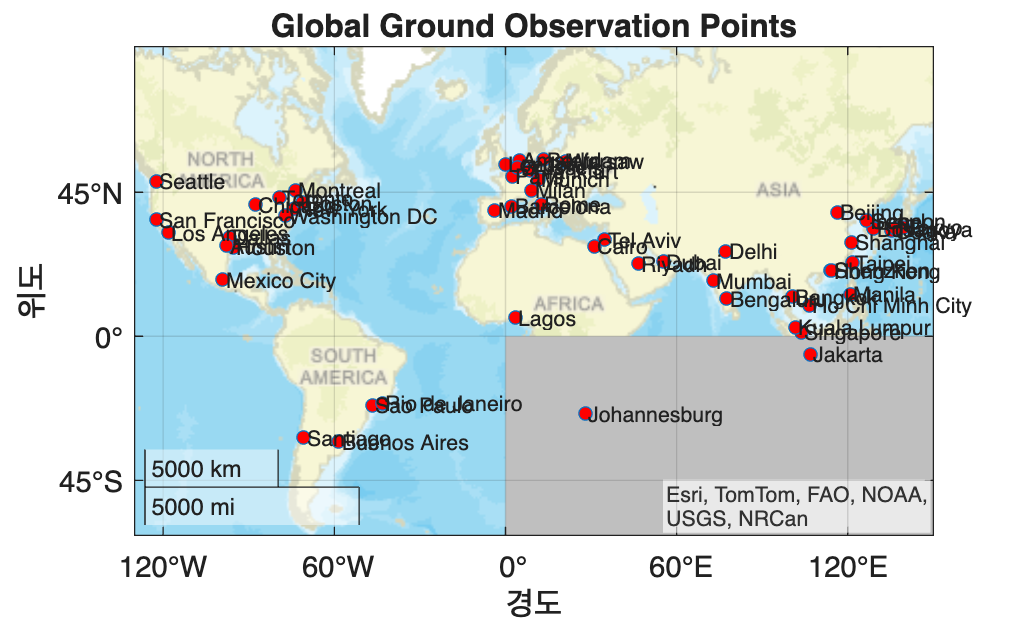


gs = groundStation(sc, lats, lons, ...
    "Name", "Ground_Point_" + string(1:N)');

set(gs,'ShowLabel',0)
set(gs,'MarkerSize',3)
set(gs,'MarkerColor','m')


figure;
geoplot(lats, lons, ...
    'Marker','o', ...
    'LineStyle','none', ...
    'MarkerSize',5, ...
    'MarkerFaceColor','r')

geobasemap streets

geolimits([-40 60], [-130 150])

title('Global Ground Observation Points', ...
    'FontSize',12, ...
    'FontWeight','bold')

for k = 1:N
    text(lats(k), lons(k)+1, cityNames(k),'FontSize',8)
end



SAT_GS_access_sequence = [];
 for Payload_index = 1:length(Payload_list)
     % EOIR_payload_index % 계산속도 체크용
     SAT_GS_access_sequence = [SAT_GS_access_sequence,access(gs, Payload_list(Payload_index))];
 end    

SAT_GS_access_interval = accessIntervals(SAT_GS_access_sequence);
filename = ['Scenario_' num2str(number_of_satellites) '_SATs_' num2str(number_of_orbit_planes) '_Orbit_Planes_' num2str(inclination_angle) '_inc_' num2str(sim_duration) 'days_access_interval'];
fullname = fullfile(savepath,filename);
save(fullname,'SAT_GS_access_interval')

% CSV 파일로도 저장
csv_fullname = [fullname, '.csv'];
writetable(SAT_GS_access_interval, csv_fullname);